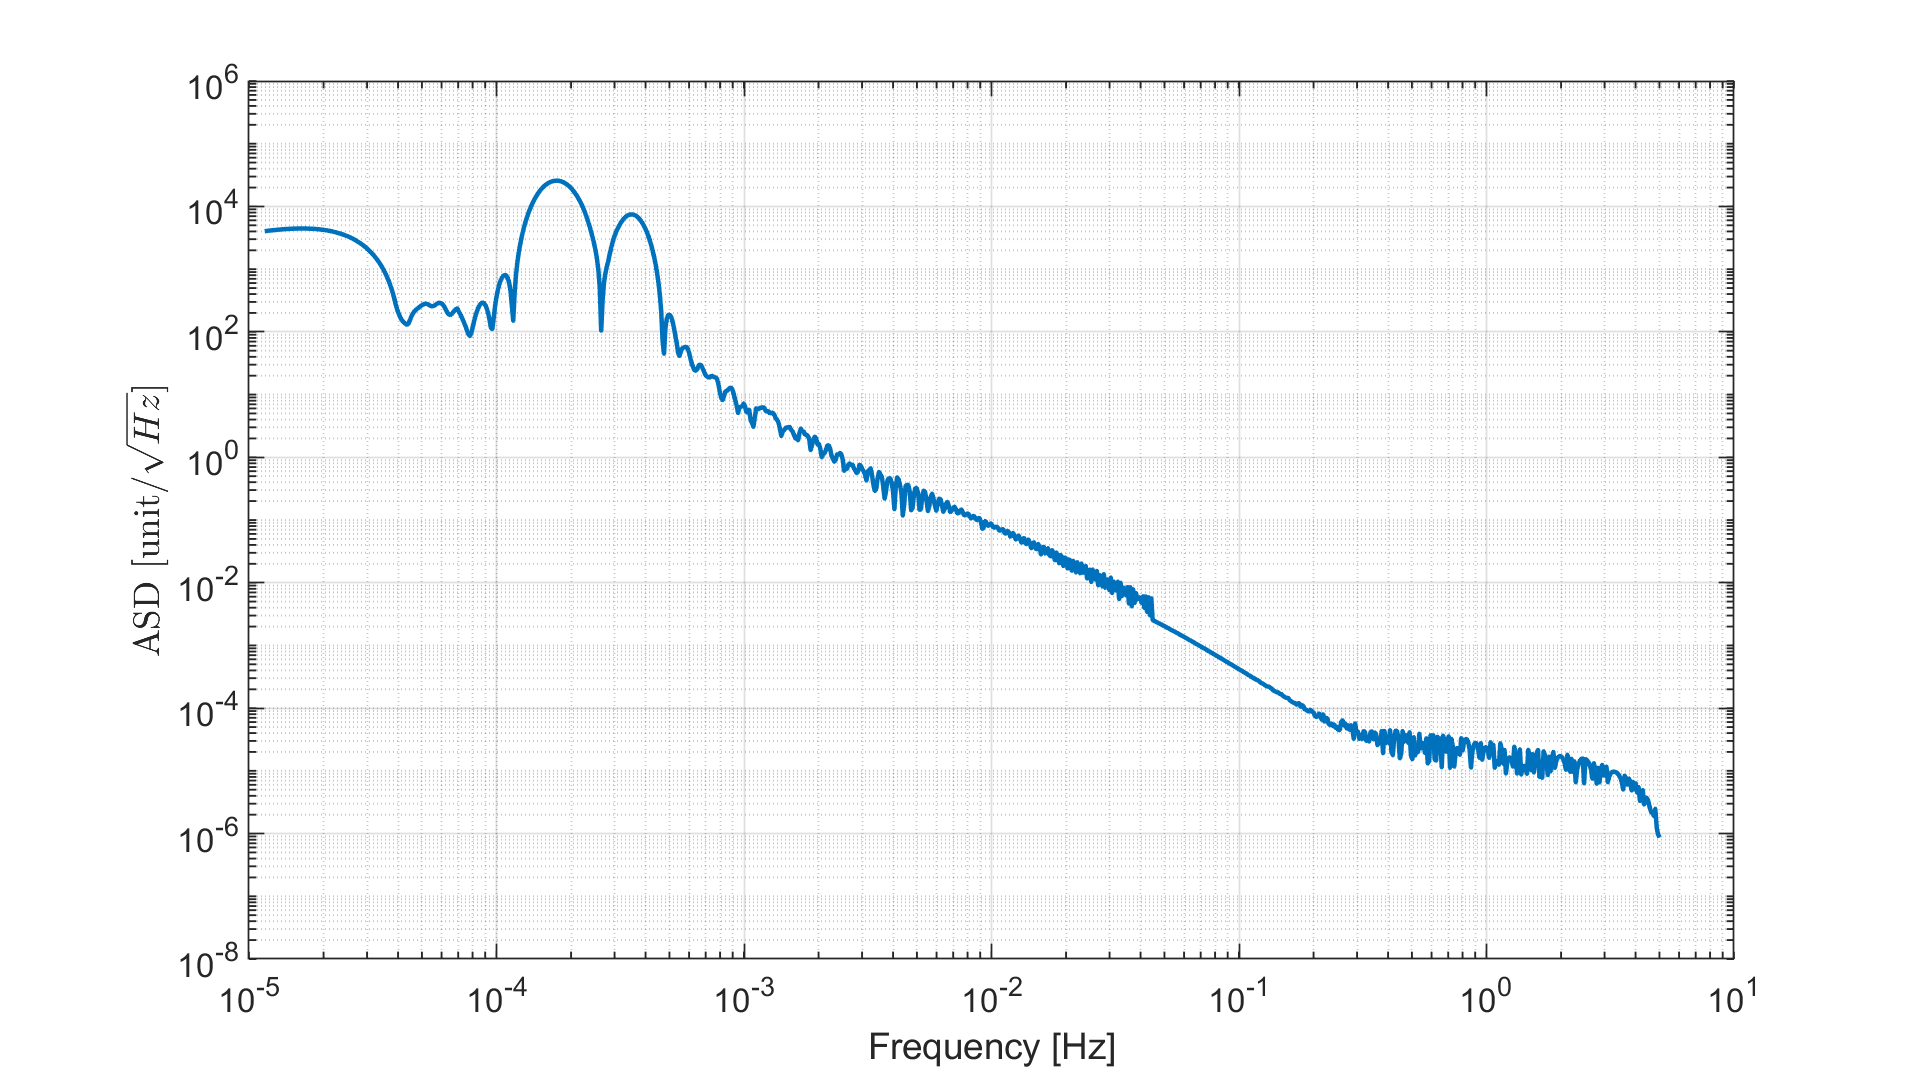

dd_range = importdata("../../../gracefo_dataset/gracefo_1A_2019-01-01_RL04.ascii.noLRI/DDR1A_2019-01-01_Y_04.txt");
dd_range = dd_range(100: end - 100) - mean(dd_range);

%new_figure;
%lpsd_plot(dd_range, @hanning, 10/length(dd_range), 5, 1000, 100, 2, 10, 0.5)
%semilogx(linspace(0.0001, 5, 10000), 2.62 .* sqrt(1. + (0.003 ./ linspace(0.0001, 5, 10000).^2)) .* 1e-6, "LineWidth", 2)
dowr1a = importdata("../../../gracefo_dataset/gracefo_1A_2018-12-01_RL04.ascii.noLRI/DOWR1A_2018-12-01_Y_04.txt");
new_figure;
lpsd_plot(dowr1a(:, 2), @hanning, 10/length(dowr1a(:, 2)), 5, 1000, 100, 2, 10, 0.5)